% generate some fake data
x = [0.84 0.29 0.84 0.85 0.021 0.52 1 0.64 0.27 0.55 0.078 0.26 0.78 0.67 0.37 0.22 0.62 0.39 0.71 0.24];
y = [0.52 0.38 0.21 0.27 0.83 0.65 0.64 0.26 0.34 0.55 0.87 0.21 0.22 0.84 0.42 0.23 0.68 0.68 0.64 0.61];

% compute the actual correlation value observerd

actualcorr = corr(x(:),y(:));


% we pose the null hypothesis (we first distrust the statement there IS the
% correlation between two distributions) that there is no dependency
% between the x-value and the y-value. Thus, under the null hypothesis, we
% should be able to break the association between x and y.

% perform randomization
results = zeros(1,10000);

for num=1:10000
    
    % vector of indices ( a random ordering of the integers between 1 and n
    % where n is the number of data points)
    
    ix = randperm(length(x));
    
    % compute correlation between randomly shuffled x-values and the
    % y-values
    
    results(num) = corr(x(ix)', y');
end

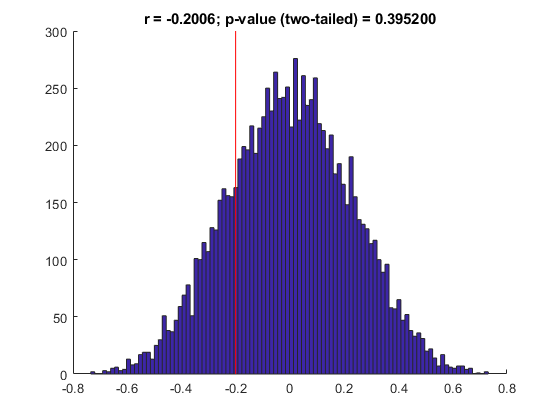

% visualize 

figure; hold on;
hist(results, 100);
ax = axis;

plot(repmat(actualcorr, [1 2]), ax(3:4), 'r-')

    % compute the p-value as the fraction of the distribution that is more
    % extreme than the actually obsevrved correlation value. We use
    % absolute value so that both positive and negative correlations count
    % as "extreme". This is referred to as a two-tailed test
    
pval = sum(abs(results) > abs(actualcorr)) / length(results);

title(sprintf("r = %.4f; p-value (two-tailed) = %.6f", actualcorr, pval));



%   the actual correlation value (-0.2) is fairly weak. under the null
%   hypothess, we would expect to find correlation values of that size or
%   larger about %40 of the time. Thus, we do not have sufficient evidence
%   to reject the null hypothesis. In orther words, the actual correlation
%   value observed is deemed not statistically significant.